clc
clear
load('wheat_line_sway.mat')
force_frequency_list = force_frequency_list(1,1:size(result,2));

% clf
% figure(1)
% for i=1:size(force_frequency_list,2)
%     plot(result(i).y.Time,squeeze(result(i).y.Data(1,1,:)),'DisplayName',['freq=' force_frequency_list(i) ' rad/s'])
%     hold on
% end
% legend
% xlabel('force frequency (rad/s)')
% ylabel('y (m)')
% title('Occilation plot')

clf
figure(3)
i = 30;
plot(result(i).y.Time,squeeze(result(i).y.Data(10,1,:)))
xlabel('time (s)')
ylabel('y (m)')
title('Occilation plot')


% y_fft = fft(squeeze(out.z.Data(20,1,:)));
% n = length(out.y.Time);
% f = 2*pi*(0:n-1)/out.y.Time(n);
% % k cycles per N samples
% figure(4)
% plot(f(2:end),abs(y_fft(2:end)),"LineWidth",3)
% % xlim([-0.5 1.5])
% % ylim([0 4.5e4])
% xlabel('Frequency (rad/s)')
% ylabel('Magnitude')
% title('FFT plot')

% force_freq_order = 30;
% wheat_order = 20;
time_step = 0.001;

for force_freq_order=29:size(force_frequency_list,2)
    for wheat_order=1:20
        y_fft = fft(squeeze(result(force_freq_order).y.Data(wheat_order,1,:)));
        N = length(result(force_freq_order).y.Time);
        % f = 2*pi*(0:N-1)/result(force_freq_order).y.Time(N);
        f = 2*pi*(0:N-1)/(N*time_step);
        % k cycles per N samples
        fig = figure(1);
        plot(f(2:end),abs(y_fft(2:end)),"LineWidth",3)
        % xlim([-0.5 1.5])
        % ylim([0 4.5e4])
        xlabel('Frequency (rad/s)')
        ylabel('Magnitude')
        title(['FFT plot with'' force freq=' num2str(force_frequency_list(force_freq_order)) ' wheat order=' num2str(wheat_order)])
        xlim([0 200])
        set(fig, 'PaperPositionMode', 'auto')
        image_name=['force_freq=' num2str(force_frequency_list(force_freq_order)) '_wheat_order=' num2str(wheat_order) '.png'];
        saveas(fig,['wheat_line_analysis_image/' image_name])
        clf(fig)
    end
end

time_step = 0.001;

for force_freq_order=12:size(force_frequency_list,2)
    N = length(result(force_freq_order).y.Time);
    sum_fft = zeros([N 1]);
    for wheat_order=1:20
        y_fft = abs(fft(squeeze(result(force_freq_order).y.Data(wheat_order,1,:))));
        sum_fft = sum_fft + y_fft;           
    end
    % f = 2*pi*(0:N-1)/result(force_freq_order).y.Time(N); 
    f = 2*pi*(0:N-1)/(N*time_step);
    fig = figure(1);
    plot(f(2:end),y_fft(2:end),"LineWidth",2)
    % xlim([-0.5 1.5])
    % ylim([0 4.5e4])
    xlabel('Frequency (rad/s)')
    ylabel('Magnitude')
    title(['FFT plot with'' force freq=' num2str(force_frequency_list(force_freq_order)) ' all wheats'])
    xlim([0 200])
    set(fig, 'PaperPositionMode', 'auto')
    image_name=['force_freq=' num2str(force_frequency_list(force_freq_order)) '.png'];
    saveas(fig,['wheat_line_analysis_image/' image_name])
    clf(fig)
end

% force_freq_order = 30;
% wheat_order = 3;
wheat_number = 20;
force_number = size(force_frequency_list,2);
time_step = 0.001;

omega = 16;
omega2 = 2*omega;

N = length(result(1).y.Time);
f = 2*pi*(0:N-1)/(N*time_step);
% Find the difference between the target number and each number in the list
diffList_omega = abs(f - omega);
diffList_omega2 = abs(f - omega2);

% Find the index of the smallest difference
[~, omega_index] = min(diffList_omega);
[~, omega2_index] = min(diffList_omega2);

amp_omega_list = zeros([wheat_number,force_number]);
amp_omega2_list = zeros([wheat_number,force_number]);
amp_wind_freq_list = zeros([wheat_number,force_number]);

for force_freq_order=1:force_number
    wind_freq = force_frequency_list(force_freq_order);
    diffList_wind_freq = abs(f - wind_freq);
    [~, wind_freq_index] = min(diffList_wind_freq);
    
    for wheat_order =  1:wheat_number
        y_fft = fft(squeeze(result(force_freq_order).y.Data(wheat_order,1,:)));
        
        amp_omega_list(wheat_order,force_freq_order) = abs(y_fft(omega_index));
        amp_omega2_list(wheat_order,force_freq_order) = abs(y_fft(omega2_index));
        
        amp_wind_freq_list(wheat_order,force_freq_order) = abs(y_fft(wind_freq_index));
    end
end

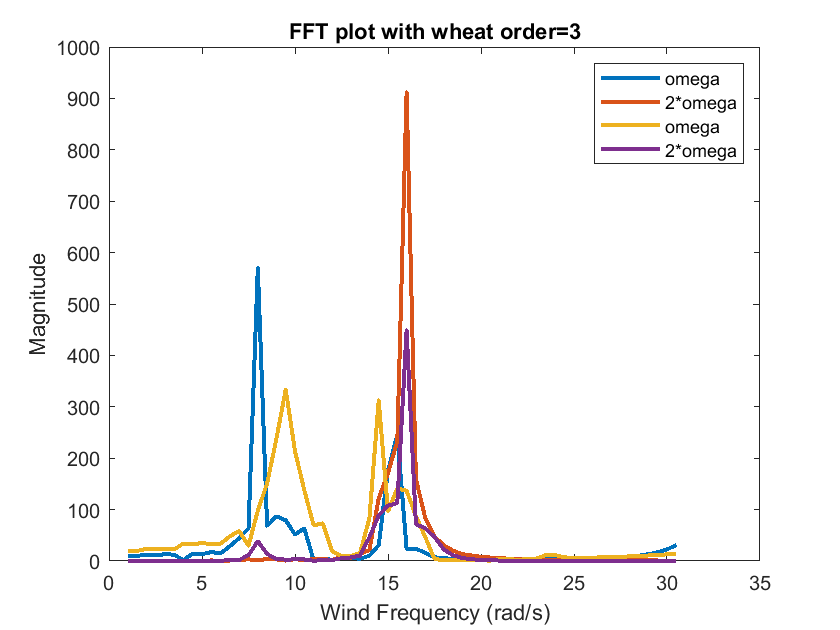

fig = figure(1);
plot(force_frequency_list, amp_omega_list,"LineWidth",2,'DisplayName','omega')
hold on
plot(force_frequency_list, amp_omega2_list,"LineWidth",2,'DisplayName','2*omega')
% xlim([-0.5 1.5])
% ylim([0 4.5e4])
xlabel('Wind Frequency (rad/s)')
ylabel('Magnitude')
title(['FFT plot with' ' wheat order=' num2str(wheat_order)])

% xlim([0 200])
legend()
set(fig, 'PaperPositionMode', 'auto')
image_name=['wheat_order=' num2str(wheat_order) '.png'];
% saveas(fig,['wheat_line_analysis_image/' image_name])
% clf(fig)

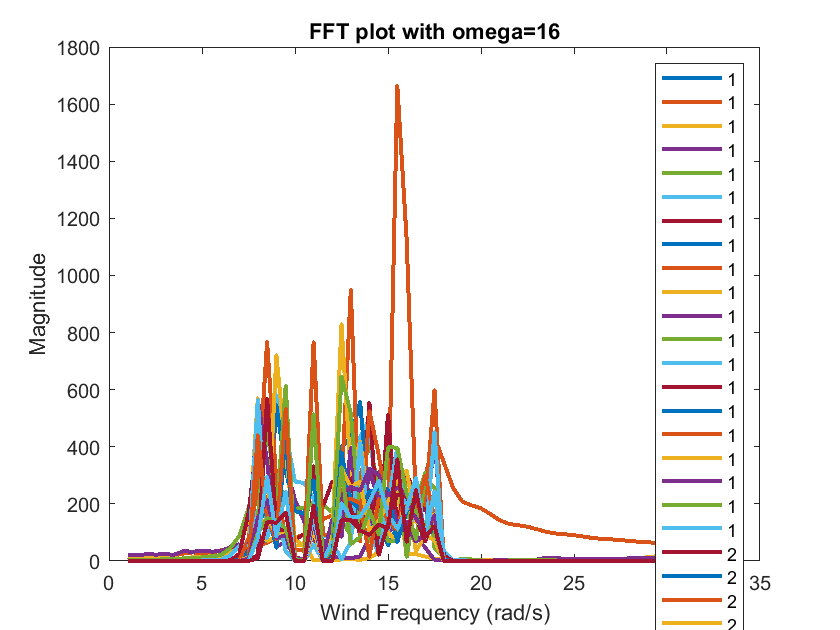

fig2 = figure(2);

for wheat_order =  1:wheat_number
    plot(force_frequency_list, amp_omega_list(wheat_order,:),"LineWidth",2,'DisplayName',int2str(wheat_order))
    hold on
end

xlabel('Wind Frequency (rad/s)')
ylabel('Magnitude')
title(['FFT plot with omega=16'])


% plot(force_frequency_list, amp_omega2_list,"LineWidth",2,'DisplayName','2*omega')
% xlim([-0.5 1.5])
% ylim([0 4.5e4])

% xlim([0 200])
legend()
set(fig, 'PaperPositionMode', 'auto')
image_name=['Freq=omega 16' '.png'];
% saveas(fig,['wheat_line_analysis_image/' image_name])
% clf(fig)

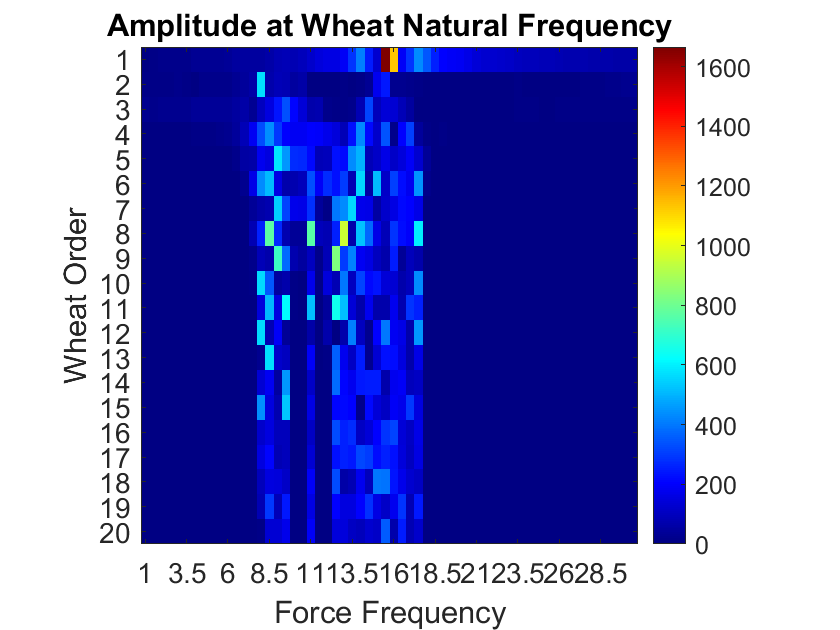

% Generate the 2D image
figure;
imagesc(amp_omega_list);
axis square; % to ensure the image is square in shape

% Customize the color map
colormap(jet); % use any colormap that suits your needs

% Add colorbar
colorbar;

% Set labels and title
xlabel('Force Frequency');
ylabel('Wheat Order');
title('Amplitude at Wheat Natural Frequency');

% Set FontSize for better visualization
set(gca, 'FontSize', 14);

% If you want to change the ticks on the axes to certain values, use the following commands:
% Set xticks at specific points and label them with the force frequency values
xticks(1:5:60); % adjust the spacing as needed
xticklabels(force_frequency_list(1:5:60)); % adjust the indexing as needed, this assumes that force_frequency_list has values for these indices

yticks(1:1:20); % adjust as needed

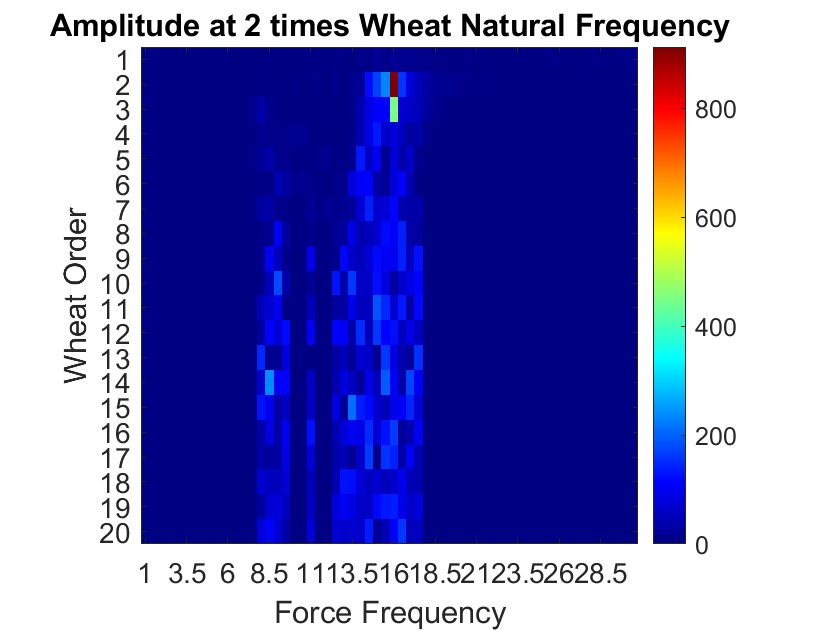

% Generate the 2D image
figure;
imagesc(amp_omega2_list);
axis square; % to ensure the image is square in shape

% Customize the color map
colormap(jet); % use any colormap that suits your needs

% Add colorbar
colorbar;

% Set labels and title
xlabel('Force Frequency');
ylabel('Wheat Order');
title('Amplitude at 2 times Wheat Natural Frequency');

% Set FontSize for better visualization
set(gca, 'FontSize', 14);

% If you want to change the ticks on the axes to certain values, use the following commands:
% Set xticks at specific points and label them with the force frequency values
xticks(1:5:60); % adjust the spacing as needed
xticklabels(force_frequency_list(1:5:60)); % adjust the indexing as needed, this assumes that force_frequency_list has values for these indices

yticks(1:1:20); % adjust as needed

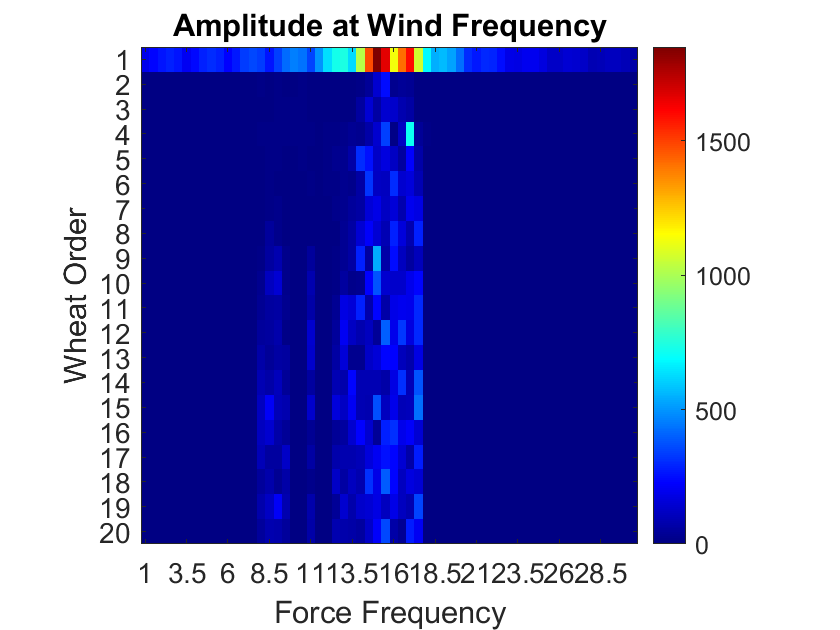

% Generate the 2D image
figure;
imagesc(amp_wind_freq_list);
axis square; % to ensure the image is square in shape

% Customize the color map
colormap(jet); % use any colormap that suits your needs

% Add colorbar
colorbar;

% Set labels and title
xlabel('Force Frequency');
ylabel('Wheat Order');
title('Amplitude at Wind Frequency');

% Set FontSize for better visualization
set(gca, 'FontSize', 14);

% If you want to change the ticks on the axes to certain values, use the following commands:
% Set xticks at specific points and label them with the force frequency values
xticks(1:5:60); % adjust the spacing as needed
xticklabels(force_frequency_list(1:5:60)); % adjust the indexing as needed, this assumes that force_frequency_list has values for these indices

yticks(1:1:20); % adjust as needed

xline(force_frequency_list(force_freq_order));
xline(15);

x = out.x.Time;
y = squeeze(out.x.Data(20,1,:));

Ts = 0.001;
fs = 1/Ts;
n = length(x);
fshift = (-n/2:n/2-1)*(fs/n);
yshift = fftshift(y);
plot(fshift,abs(yshift))
xlabel('Frequency (Hz)')
ylabel('Magnitude')
